Kp= 1131.7;
Ki=35;
Kd=22;
simulationOutput = sim('B_MotorSpeed_Task3');

simulationOutputSignals = simulationOutput.yout;
time = simulationOutput.tout;
input = simulationOutputSignals{1};
output= simulationOutputSignals{2};

t= simulationOutputSignals{2}.Values.time;
d= simulationOutputSignals{2}.Values.Data;
stepinfo(t,d,0,100)

ans = struct with fields:
         RiseTime: 0
    TransientTime: NaN
     SettlingTime: NaN
      SettlingMin: 0
      SettlingMax: 20
        Overshoot: 0
       Undershoot: 0
             Peak: 100
         PeakTime: 0


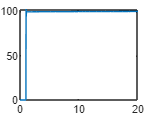

plot(t,d)

simulationOutputSignals{2}.Values.Data(end)

ans = 99.5449





simulationStoptime = time(end);
Risetime_HValue = input.Values.Data(end)*0.9; %check if input to check or output
Risetime_LValue = input.Values.Data(end)*0.1;

% for i = output.Values.Data'
%     if(i == Risetime_HValue)
%         currentRisetimeHvalue = i;
%         break;
%     else
%         continue;
%     end
% end
% 
% for i = output.Values.Data'
%     if(i == Risetime_LValue)
%         currentRisetimeLvalue = i;
%         break;
%     else
%         continue;
%     end
% end


%-------Overshoot check---------
for i = output.Values.Data'
    if(i >input.Values.Data(end)+input.Values.Data(end)*0.05)
        OverShootStatus =1;
        break
    else
        OverShootStatus=0;
        continue
    end
end
 


%------SteadyStateErrorCheck--------
currentFinalOutputValue = output.Values.Data(end)

currentFinalOutputValue = 99.5449

if(currentFinalOutputValue == input.Values.Data(end))
    SteadyState=0
else
    SteadyState=1
end

SteadyState = 1